### 1.  line continuation operator 

  一般在编辑器里一行代码太长写不下了，用...表示续行，下一行的代码和上一行是连着的

cmap = [1 1 1; ...%  1 - white - 空地
    0 0 0; ...% 2 - black - 障碍
    1 0 0; ...% 3 - red - 已搜索过的地方
    0 0 1; ...% 4 - blue - 下次搜索备选中心
    0 1 0; ...% 5 - green - 起始点
    1 1 0;...% 6 - yellow -  到目标点的路径
    1 0 1];% 7 - -  目标点

### 2.image(x,y,C)

绘制网格，image(x,y,C),如果x,y是一个数，表示起始坐标（坐标间距为1）；

如果为一个二维数组，表示起止坐标，间距自适应计算

如果为一个多维数组，用起止的元素数，表示起止坐标，间距自适应计算

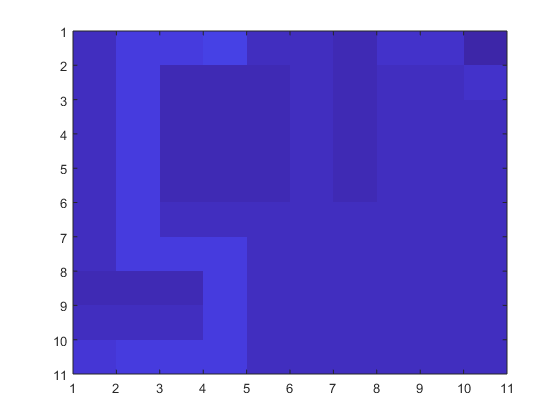

image(1.5, 1.5, map1); %绘制网格，image(x,y,C),如果x,y是一个数，表示起始坐标（坐标间距为1）；

%如果为一个二维数组，表示起止坐标，间距自适应计算
%如果为一个多维数组，用起止的元素数，表示起止坐标，间距自适应计算

### 3.`drawnow`

修改图形对象并且需要在屏幕上立即查看这次更新

drawnow %基础使用
drawnow limitrate %跳过更新以产生更快的动画,将更新数量限制为每秒 20 帧，距离上一次改变50ms内的新改变将会被遗弃

### 4.计时器

tic;
toc;

### 5.min

M = min(A);%返回数组的最小元素。


- 如果 `A` 是向量，则 `min``(A)` 返回 `A` 的最小值。

- 如果 `A` 为矩阵，则 `min``(A)` 是包含每一列的最小值的行向量。

- 如果 `A` 是多维数组，则 `min``(A)` 沿大小不等于 `1` 的第一个数组维度计算，并将这些元素视为向量。此维度的大小将变为 `1`，而所有其他维度的大小保持不变。如果 `A` 是第一个维度为 `0` 的空数组，则 `min``(A)` 返回与 `A` 大小相同的空数组。

[M,I] = min(A(:));

 M 返回A 的最小值，I返回最小值的索引。如果最大值出现多次，则 min 返回对应于第一次出现位置的索引。

[M,I] = min(A);%A为二维矩阵

M返回一个行向量，每一列都是A的每一列的最小值。

I也返回一个行向量，对应的是M每一个元素在A中的索引。

### 6.ind2sub

从线性索引映射到坐标索引

注意：对于二维矩阵，线性索引是从上到下，从左至右，按列排号的。

而矩阵中表示则是按行显示排的

如：

IND = [3 4; 5 6]，结果为

`IND = ``2×2`

`     3     4`

`     5     6`

`对于该函数而言：`

`[I,J] = ind2sub([矩阵],线性索引)`

`在矩阵中，线性索引对应的坐标位置`

IND = [3 4; 5 6];
s = [3,3];
[I,J] = ind2sub(s,IND);
%即

### 7.size

sz = size(A);

返回一个行向量，其元素包含 `A` 的相应维度的长度。例如，如果 `A` 是一个 3×4 矩阵，则 `size(A)` 返回向量 `[3 4]`。

dim = 2;
szdim = size(A,dim);

返回维度 `dim` 的长度。

%[sz1,...,szN] = size(A)

时间已过 0.000042 秒。


ans =      1
     2
     1
     1


分别返回 `A` 的每个维度的长度。

8.

(neighbor(:,1)>2) + (neighbor(:,1)>nrows) +(neighbor(:,2)>1) + (neighbor(:,2)>ncols )